# Compute a IMC controller to ensure a settling time of the closed loop system less than 5 seconds

### Compute and declare my transfer function

The transfer function has the following form:


$$H_f \left(s\right)=\frac{K_f }{s\left(T_f s+1\right)}$$


Knowing that my values are Kf = 4 and  Tf = 8, the function becomes:


$$H_f \left(s\right)=\frac{4}{s\left(8s+1\right)}$$


I declare my transfer function in code:

Kf = 4;
Tf = 8;
Hf = tf(Kf,[Tf 1 0]);

### Separate my function into good part and bad part

Pg = Hf; %% good part
Pb = 1; %% bad part

### Invert the good part

Pg_inv = inv(Pg)

Pg_inv =
 
  8 s^2 + s
  ---------
      4
 
Continuous-time transfer function.



### Apply a filter of order of the good part denominator

Pg

Pg =
 
      4
  ---------
  8 s^2 + s
 
Continuous-time transfer function.



order = 2; %% order of the good part denominator

Calculate starting value for lambda

lambda = Tf/10;

Calculate filter's denominator

den = $\left(\lambda s+1\right)*\left(\lambda s+1\right)=\lambda^2 s^2 +2\lambda s+1$

filter = tf(1,[lambda^2 2*lambda 1])

filter =
 
           1
  --------------------
  0.64 s^2 + 1.6 s + 1
 
Continuous-time transfer function.



### Calculate the equivalent controller

C = minreal(Pg_inv*filter)

C =
 
  3.125 s^2 + 0.3906 s
  --------------------
  s^2 + 2.5 s + 1.562
 
Continuous-time transfer function.



R = minreal(C/(1-C*Hf))

R =
 
  3.125 s^2 + 0.7812 s + 0.04883
  ------------------------------
      s^2 + 2.625 s + 0.3125
 
Continuous-time transfer function.



### Compute the closed loop

Ho = minreal(R*Hf/(1+R*Hf))

Ho =
 
        1.562 s^4 + 0.7812 s^3 + 0.1465 s^2 + 0.01221 s + 0.0003815
  ------------------------------------------------------------------------
  s^6 + 3 s^5 + 2.906 s^4 + 1.023 s^3 + 0.1663 s^2 + 0.01282 s + 0.0003815
 
Continuous-time transfer function.



% step(Ho)

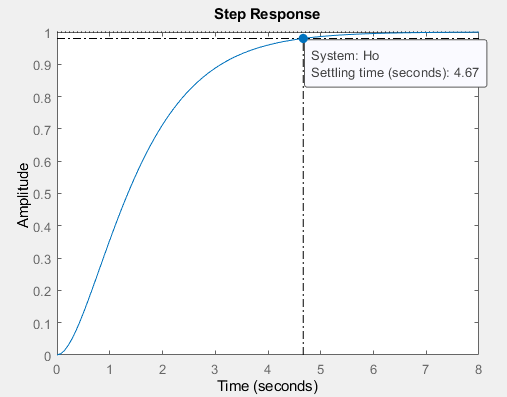

### Symulink

#### Without saturation and with a perturbation of value 5

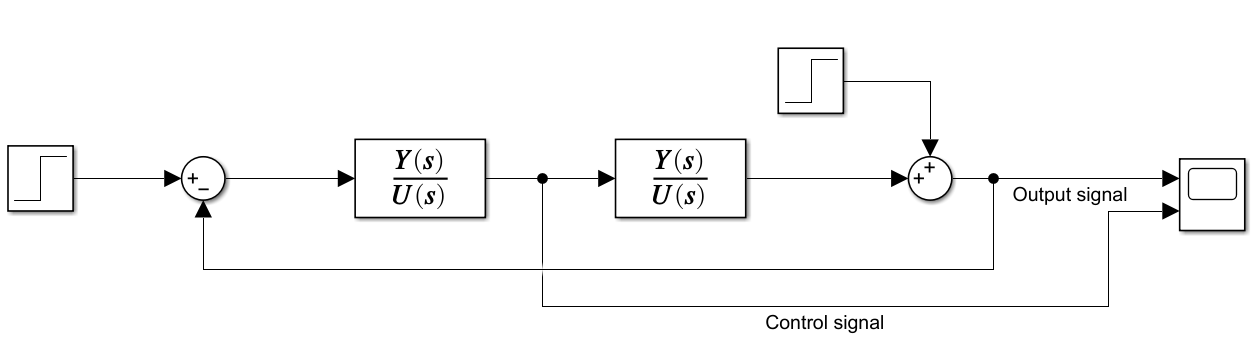

Without a limitation, the controller can generate a signal as big as it needs in order to get the output at the steady state value in the same settling time disregarding the value of the perturbation.

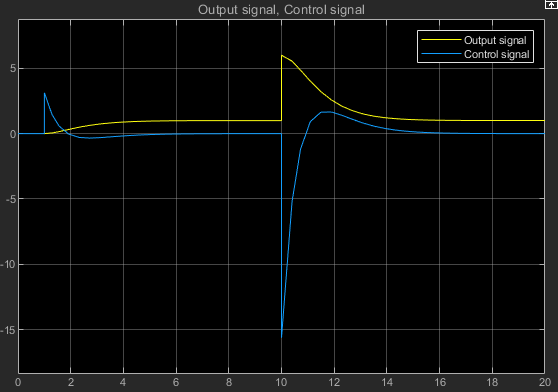

#### With saturation between [-1,1] and same value of perturbations

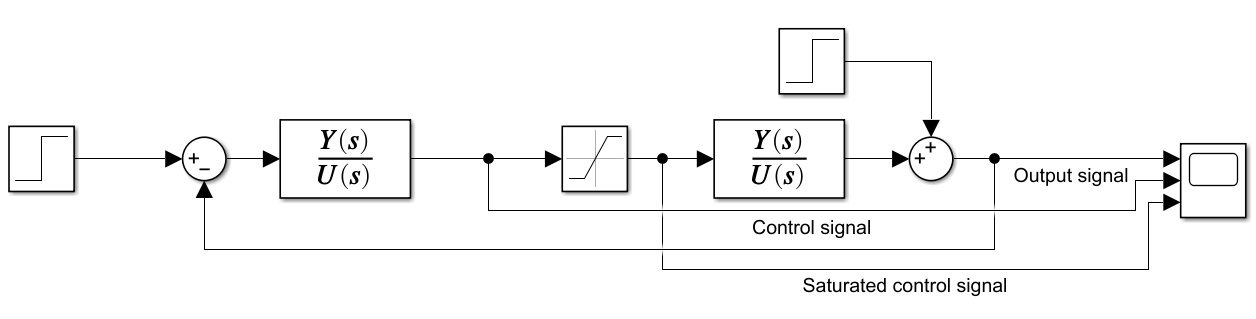

In a realistic situation our controller will be greatly affected by the value of the perturbations, because the control signal can't pass the physical limitations, in our case [-1,1], so the settling time will raise with the increasing value of the perturbations.